Observe the area of depleted cellulose around a colony

Horizontal slice of cellulose amount for various alphas

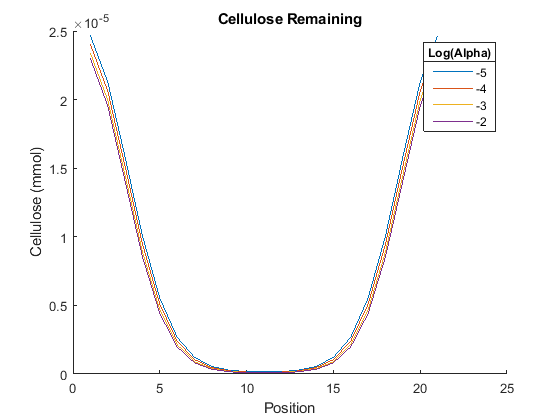

alphas = unique(dat5.alpha);
figure();
hold on;
for i = 1:length(alphas)
    row = dat5(dat5.alpha == alphas(i),:);
    media = row.media{1};
    tmax = max(media.t);
    media = media(media.t == tmax,:);
    cel = media(strcmp('cellulose',media.metname),:);
    xmax = max(media.x);
    xmid = ceil(xmax);
    cel = cel(cel.x == xmid,:);
    plot(cel.y,cel.amt);
    ydat(i) = {cel.amt};
end
hold off;
leg = legend(num2str(log(alphas)));
title(leg,'Log(Alpha)');
title('Cellulose Remaining');
ylabel('Cellulose (mmol)');
xlabel('Position');

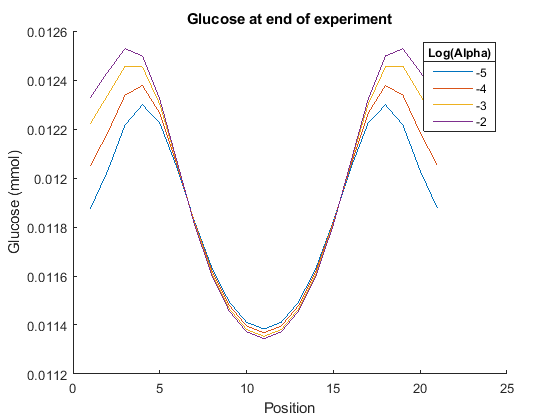

alphas = unique(dat5.alpha);
figure();
hold on;
for i = 1:length(alphas)
    row = dat5(dat5.alpha == alphas(i),:);
    media = row.media{1};
    tmax = max(media.t);
    media = media(media.t == tmax,:);
    glc = media(strcmp('glc-D[e]',media.metname),:);
    xmax = max(media.x);
    xmid = ceil(xmax);
    glc = glc(glc.x == xmid,:);
    plot(glc.y,glc.amt);
    ydat(i) = {glc.amt};
end
hold off;
leg = legend(num2str(log(alphas)));
title(leg,'Log(Alpha)');
title('Glucose at end of experiment');
ylabel('Glucose (mmol)');
xlabel('Position');

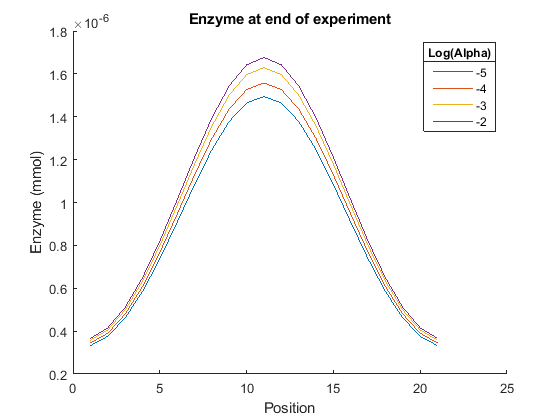

alphas = unique(dat5.alpha);
figure();
hold on;
for i = 1:length(alphas)
    row = dat5(dat5.alpha == alphas(i),:);
    media = row.media{1};
    tmax = max(media.t);
    media = media(media.t == tmax,:);
    enz = media(strcmp('enzyme[e]',media.metname),:);
    xmax = max(media.x);
    xmid = ceil(xmax);
    enz = enz(enz.x == xmid,:);
    plot(enz.y,enz.amt);
    ydat(i) = {enz.amt};
end
hold off;
leg = legend(num2str(log(alphas)));
title(leg,'Log(Alpha)');
title('Enzyme at end of experiment');
ylabel('Enzyme (mmol)');
xlabel('Position');

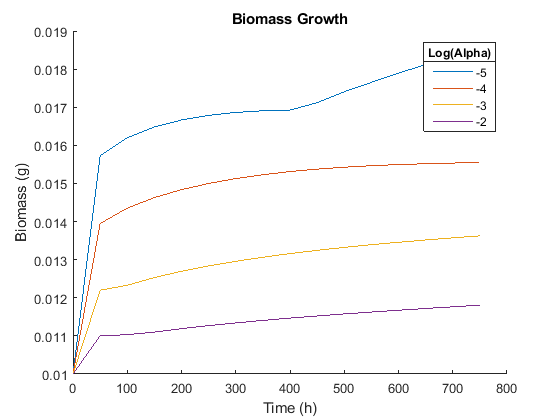

alphas = unique(dat5.alpha);
figure();
hold on;
for i = 1:length(alphas)
    row = dat5(dat5.alpha == alphas(i),:);
    biomass = row.biomass{1};
    plot(biomass.t,biomass.biomass);
end
hold off;
leg = legend(num2str(log(alphas)));
title(leg,'Log(Alpha)');
title('Biomass Growth');
xlabel('Time (h)');
ylabel('Biomass (g)');